## Importing the Data

tic
crashdata = table2struct(webread("https://data.cityofnewyork.us/api/views/h9gi-nx95/rows.csv?accessType=DOWNLOAD"));

## Scrubbing the Data

Determining the size of the dataset, as well as how many points are actually going to be analyzed.

[r,~] = size(crashdata);
fprintf("There are a total of %d datapoints\n",r)
fprintf("Since we don't want nearly that many datapoints, we'll use one random point in ever 50 in the set\n")
format long g
max = floor(r/50);

%this loop eliminates all datapoints outside 
for i = r:-1:(max*50)+1
    crashdata(i) = [];
end

%under this, the last row of cleandata is given the last row of crashdata.
%This is temporary, and used to allow preallocation.
clear cleandata
cleandata(max) = crashdata(max*50);
for i = 1:max
    rannum = randi([1,50]);
    cleandata(i) = crashdata(rannum + ((i-1)*50));
end

cleandata = cleandata'
[rclean,~] = size(cleandata);
fprintf("The size of the scrubbed data is now %d\n",rclean)

Now that the datapool has been decreased to a workable size, we're going to elminate datapoints that won't help us. This includes ones with no specified Borough, no specified causation factor (for at least 1 vehicle), and no specified streetname.

NB: Each step in the following scrubbing is run 5 times. MATLAB tends to miss a value occasionally, so repeating the process solves this issue.

%this loop eliminates values with no Borough
for i = 1:5
    idex = 1;
    while idex <= rclean
        if isempty(cleandata(idex).BOROUGH) || isnan(cleandata(idex).ZIPCODE)
                cleandata(idex) = [];
        end
        idex = idex + 1;
        [rclean,~] = size(cleandata);
    end
end

cleandata
%this loop elmimnates values with no streetname
for i = 1:5
    idex = 1;
    while idex <= rclean
        if isempty(cleandata(idex).ONSTREETNAME)
                cleandata(idex) = [];
        end
        idex = idex + 1;
        [rclean,~] = size(cleandata);
    end
end
cleandata
%finally, this loop eliminates datapoints with unspecified causes
for i = 1:5
    idex = 1;
    while idex <= rclean
        if  strcmp(cleandata(idex).CONTRIBUTINGFACTORVEHICLE1,'Unspecified') || isempty(cleandata(idex).CONTRIBUTINGFACTORVEHICLE1)
                cleandata(idex) = [];
        end
        idex = idex + 1;
        [rclean,~] = size(cleandata);
    end
end
cleandata
fprintf("The final size of the data is %d datapoints\n",rclean)
toc


% save cleandata.mat cleandata

Finally, the data can be analyzed in the ML Toolbox

## Vectorizing Code

In this section, three vectors are created: one is the total amount of people killed per crash, another is the total amount of those injured, and the last is the time of each of the crashes. These will be used in the machine learning toolbox. We 

load cleandata.mat
[rclean, cclean] = size(cleandata);
kills = zeros(rclean,1);
for i = 1:rclean
    kills(i) = cleandata(i).NUMBEROFPERSONSKILLED + cleandata(i).NUMBEROFPEDESTRIANSKILLED + cleandata(i).NUMBEROFCYCLISTKILLED + cleandata(i).NUMBEROFMOTORISTKILLED;
end
kills

kills =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


injurs = zeros(rclean,1);
for i = 1:rclean
    injurs(i) = cleandata(i).NUMBEROFPERSONSINJURED + cleandata(i).NUMBEROFPEDESTRIANSINJURED + cleandata(i).NUMBEROFCYCLISTINJURED + cleandata(i).NUMBEROFMOTORISTINJURED;
end
injurs

injurs =      2
     2
     2
     0
     6
     0
     6
     0
     0
     0


time = zeros(rclean,1);
for i = 1:rclean
    temp = cleandata(i).CRASHTIME;
    time(i) = str2double(erase(temp, ':'));
end
time

time =          102
        1755
         840
        2221
           0
         315
        1030
        1700
        1138
        1730


%learnerinfo = table(injurs,kills,boroughs)
save times.mat time
save injuries.mat injurs
save kills.mat kills

## **Using Kill and Injurs Data**

suminj = zeros(1,48);
lbt = 0;
hbt = 50;
for i = 1:48
    lbt = 0 + 50 * (i-1);
    hbt = 50 + 50 * (i-1);
    for j = 1:length(cleandata)
        if (str2double(erase(cleandata(j).CRASHTIME,':')))  >=lbt-20 && (str2double(erase(cleandata(j).CRASHTIME,':'))  < hbt-20 )
        suminj(i) = suminj(i) + cleandata(j).NUMBEROFPERSONSINJURED + cleandata(j).NUMBEROFPERSONSKILLED + cleandata(j).NUMBEROFPEDESTRIANSINJURED + cleandata(j).NUMBEROFPEDESTRIANSKILLED + cleandata(j).NUMBEROFMOTORISTINJURED;
        end
    end
end

suminj = suminj';

%% This function depends on which time interval the crash happen, it adds the injuries and deaths into the body counts in its interval

## **Using Time Data**

*Devide the whole day into 24 intervals*

lb = 0;
hb = 50;
num = 1;
tinterval = zeros(1,length(time));
while hb <= 2400
    for i = 1:length(time)
        
        if (time(i)>= lb-20 && time(i)<hb-20)
            tinterval(i) = num;
        end
    end
    num = num+1;
    lb = lb + 50;
    hb = hb + 50;
end
tinterval = tinterval';
%% this catagorize the crashe times into 48 different intervals 

Check the count of each time interval

tfreq = zeros(1,48);
while num >= 1
    for i = 1: length(time)
        if (tinterval(i) == num )
            tfreq(num) = tfreq(num) + 1;
        end
    end
    num = num -1;
end
tfreq = tfreq';

%% this count how often does crashes happens in each time intervals

Creating the timevector to graph:

timevec = strings([48,1]);
hourvec = zeros(1,48);
minvec = zeros(1,48);
sub = 0;
for i = 1:2:48
    hourvec(i) = sub;
    hourvec(i+1) = sub;
    sub = sub + 1 ;
end
for i = 1:2:48
    minvec(i) = 0;
    minvec(i+1) = 30;
end
strhour = string(hourvec);
strmin = string(minvec);
for i = 1:48 
    timevec(i) = strcat(strhour(i), "." , strmin(i));
end

timevec = str2double(timevec); %#ok<NASGU> 

%% this creats a time interval vector for machine learning

## Vectorizing v2

%length(unique(boroughs))

%boroughsandids = horzcat((unique(boroughs)), (1:5)')

% boroughsID = zeros(length(boroughs),1)
% for i = 1:length(boroughs)
% switch(boroughs(i))
%     case "BRONX"
%         boroughsID(i) = 1;
%     case "BROOKLYN"
%         boroughsID(i) = 2;
%     case "MANHATTAN"
%         boroughsID(i) = 3;
%     case "QUEENS"
%         boroughsID(i) = 4;
%     case "STATEN ISLAND"
%         boroughsID(i) = 5;
%     otherwise
%         boroughsID(i) = 0;
% end
% end
% 
% boroughsID


## Creating Regression Model and Validating

To create the model, we use the time as the input and the cumulation of deaths + injuries as the output. The model will then allow us to predict future times and their respective fatality rates for one day.

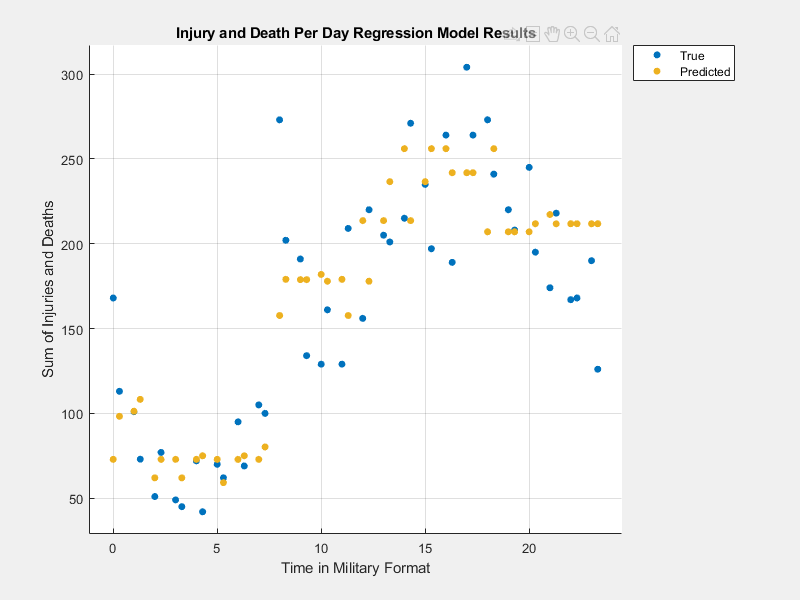

% loading the predicted and true graph to show accuracy of model for
% injuries+deaths
% these two next figures help validate the accuracy of the model
load injuryModel.mat
injuryFig = openfig('modelInjuriesPlot.fig');

figure(injuryFig)
xlabel('Time in Military Format')
ylabel('Sum of Injuries and Deaths')
title('Injury and Death Per Day Regression Model Results')
load frequencyModel.mat
frequencyFig = openfig('modelFrequencyPlot.fig');

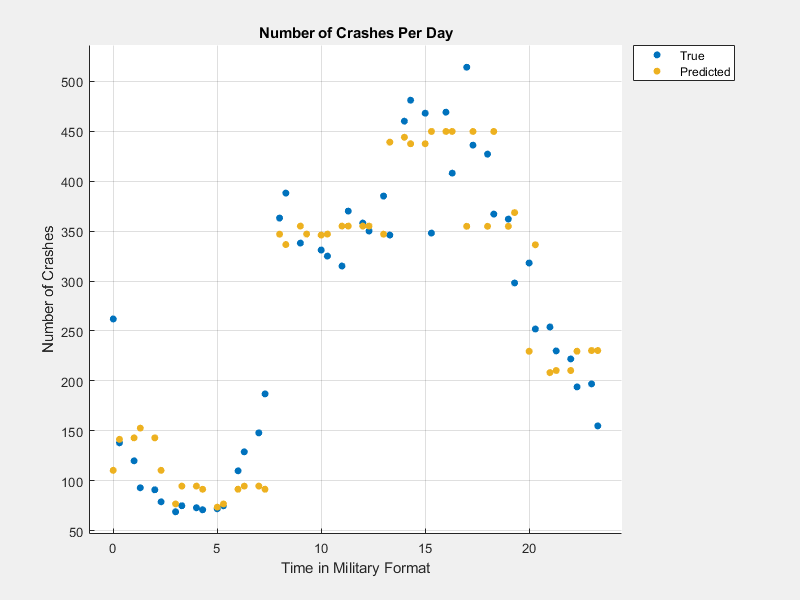

% doing the same with frequencies
figure(frequencyFig)
xlabel('Time in Military Format')
ylabel('Number of Crashes')
title('Number of Crashes Per Day')

Next section will help show a possible use case where we input random times into the model to give us results.

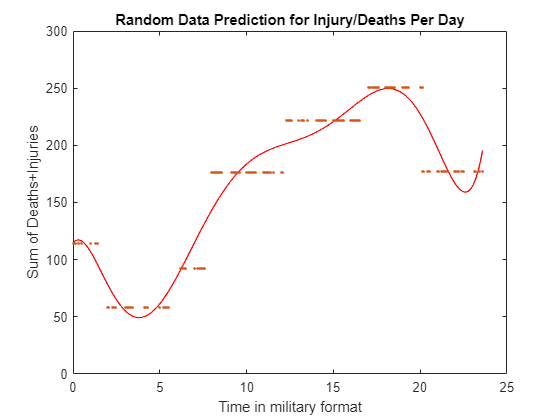

%creating a table of random data points to feed into model to show
% numerical results
load injuryModel.mat

% get random indices for the time
indices = randi([1, length(cleandata)], 300, 1);
timevec = zeros(300,1);
for i = 1:length(indices)
    temp = cleandata(i).CRASHTIME;
    timevec(i) = str2double(strrep(temp,':','.'));
end

% get predicted values
injuryTestOutput = injuryModel.predictFcn(timevec);

% polyfit
coefficients = polyfit(timevec, injuryTestOutput, 7);
xFit = linspace(min(timevec), max(timevec), 1000);
yFit = polyval(coefficients , xFit);
plot(xFit, yFit, 'r-', 'LineWidth', 1); % Plot fitted line.
hold on;

% plotting
plot(timevec, injuryTestOutput, '.')
xlabel('Time in military format')
ylabel('Sum of Deaths+Injuries')
title('Random Data Prediction for Injury/Deaths Per Day')

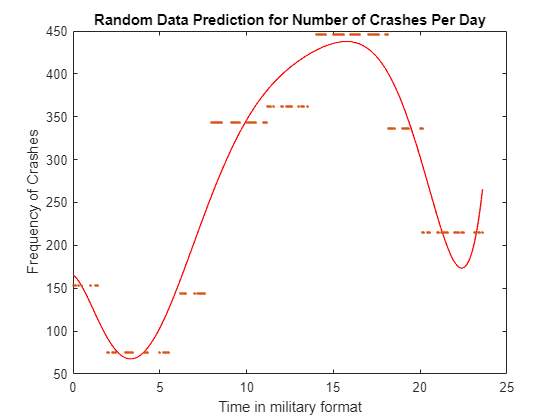

% same process for the frequency of crashes
figure
load frequencyModel.mat
frequencyTestOutput = frequencyModel.predictFcn(timevec);


% polyfit
coefficients = polyfit(timevec, frequencyTestOutput, 7);
xFit = linspace(min(timevec), max(timevec), 1000);
yFit = polyval(coefficients , xFit);
plot(xFit, yFit, 'r-', 'LineWidth', 1); % Plot fitted line.
hold on;

% plotting
plot(timevec, frequencyTestOutput, '.')
xlabel('Time in military format')
ylabel('Frequency of Crashes')
title('Random Data Prediction for Number of Crashes Per Day')
hold off

## Project Deliverables

#### Article Citation and Synopsis

#### Background and High-Level Explaination of Problem

As the most populated city in the US, New York City is also prone to an extreme amount of traffic and traffic collisions. According to [US News](https://www.usnews.com/news/cities/articles/10-cities-with-the-worst-traffic-in-the-us), New York City is the fourth most congested city in America; this is backed up by several legal firms, [one of which](https://jknylaw.com/new-york-car-accident-lawyer/statistics/) says that there were an average of 303 daily collisions in 2020. This project aims to discover what conditions in NYC are most likely to result in a collision, more specifically what time of day causes the most traffic-related injuries and deaths. The hope is that people who normally drive within the five Boroughs will look at the data and avoid driving at more dangerous times, if possible, overall decreasing the amount of injuries and casualties from traffic collisions.

#### Solution Process and Inferences

To find the answer to our problem, we first shrunk our sample size. We took one random datapoint in every 50 of the original dataset, to avoid any data bias. We then removed points missing information that may be vital: Borough, Street, and Cause of Collision. Once the data was scrubbed, we attempted to use the Classification and Regression Learners to produce valuable data; we realized that the Regression Learner would be more useful than the Classification Learner, so we stuck with that. However, our first few attempts at datamatching proved unsuccessful. The combinations of Injuries/Kills and Boroughs and Injuries/Kills and Streets didn't work, as we needed numerical values to do a true comparison. While giving the Boroughs a numerical ID would work, the result would be similar to a bar graph. Finally, we used Time against Injuries/Kills, which proved both successful and useful, so we stuck with that.

By referencing the graph, it can be inferred that the most dangerous time to drive in New York City is between 4pm and 7pm; considering that this is the usual time employees commute home, this lines up with normal logic. Therefore, the prediction data can be deemed a success.